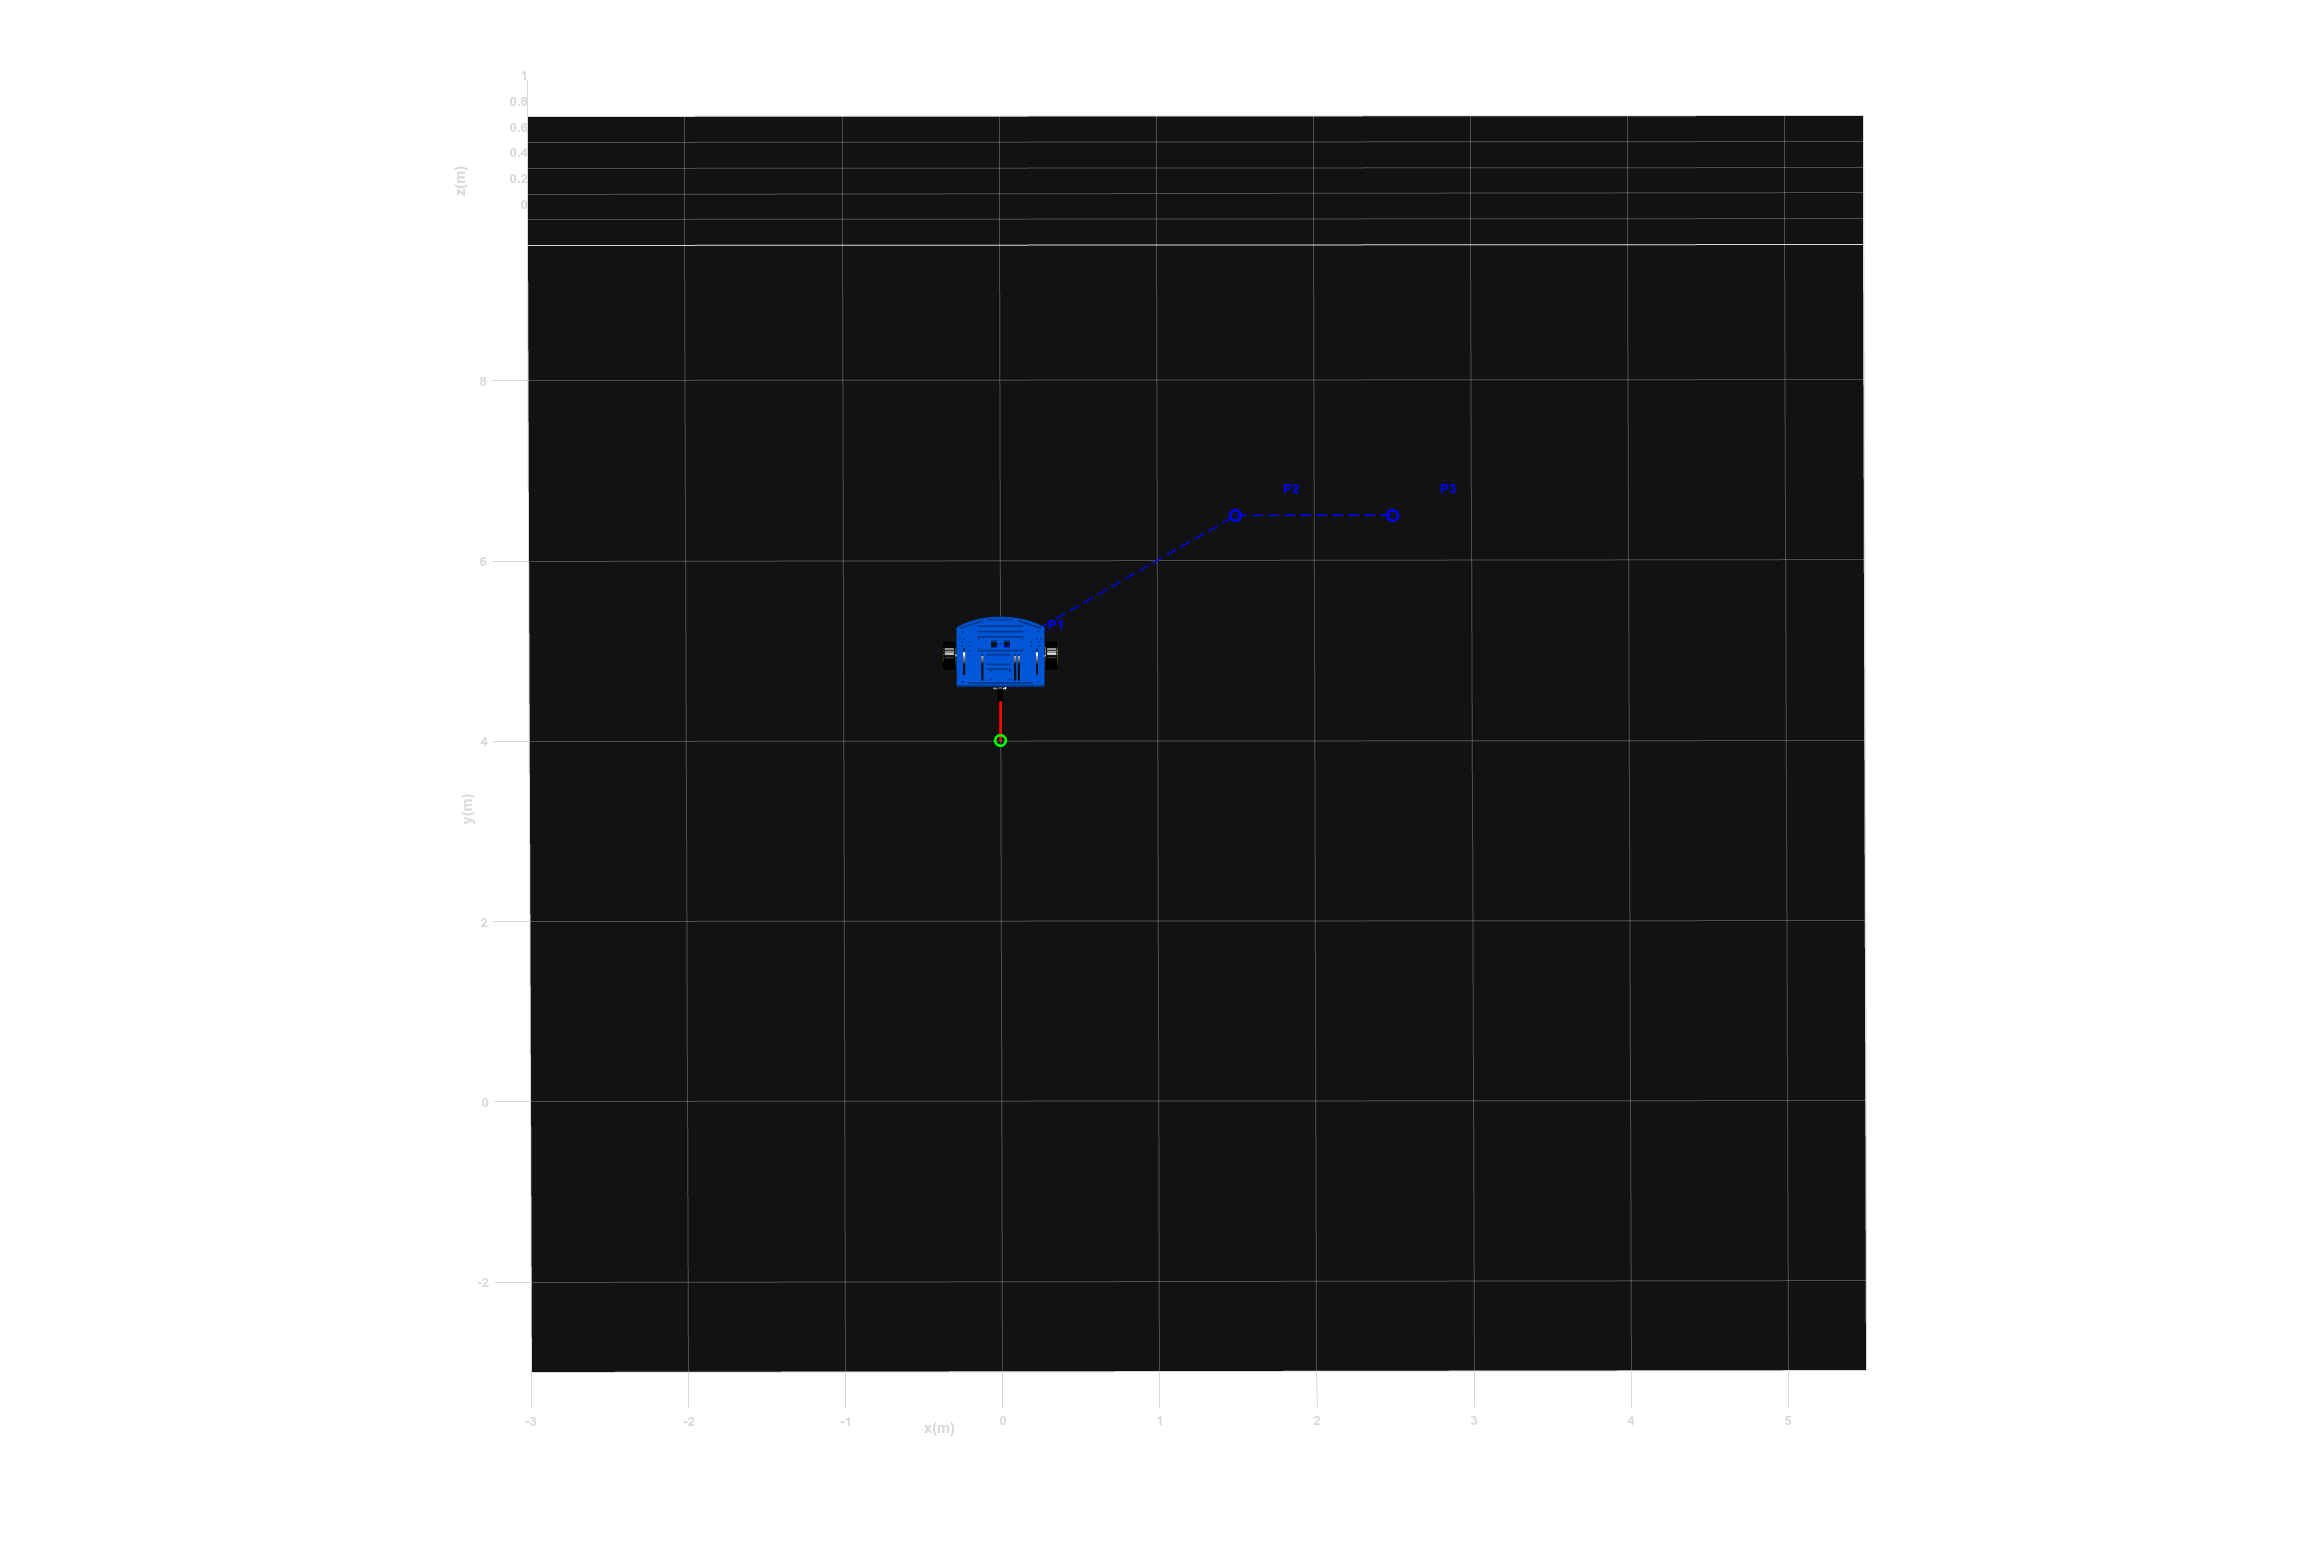

%Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ts     = 0.1;              % Tiempo de muestreo (s)
tf_max = 300;              % Tiempo máximo de seguridad (s)
N_max  = round(tf_max/ts); % Tope de muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1)  = 0;     % Posición inicial eje X
y1(1)  = 4;     % Posición inicial eje Y
phi(1) = pi/2;  % Orientación inicial

%3 WAYPOINTS (PUNTOS DESEADOS) %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cada fila es un punto [x y]. Agrega/quita los que quieras.
waypointsOriginal = [  0,   5;
                       1.5, 6.5;
                       2.5, 6.5];

% --- Densificación: subdividir cada segmento en sub-puntos ---
% Esto hace que el robot trace líneas rectas entre puntos en lugar de curvas
ds = 0.05;                            % Espaciado entre sub-puntos (m)
waypoints = waypointsOriginal(1,:);   % Empezamos con el primer punto

for i = 1:size(waypointsOriginal,1)-1
    p1 = waypointsOriginal(i,   :);
    p2 = waypointsOriginal(i+1, :);
    distSeg = norm(p2 - p1);
    nSub    = max(2, ceil(distSeg/ds));   % Número de sub-puntos en este segmento
    for j = 1:nSub
        alpha  = j/nSub;                  % Interpolación lineal de 0 a 1
        nuevoP = (1-alpha)*p1 + alpha*p2;
        waypoints = [waypoints; nuevoP];
    end
end
% -------------------------------------------------------------

numWp      = size(waypoints, 1);
tolerancia = 0.05;   % Distancia (m) para considerar el punto alcanzado

idxWp = 1;
hxd   = waypoints(idxWp, 1);
hyd   = waypoints(idxWp, 2);

hx(1) = x1(1);
hy(1) = y1(1);

%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
k = 1;
trayectoriaCompletada = false;

while ~trayectoriaCompletada && k <= N_max

    %a) Errores de control
    hxe(k)   = hxd - hx(k);
    hye(k)   = hyd - hy(k);
    Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

    % ¿Llegamos al waypoint actual? -> avanzar al siguiente
    if Error(k) < tolerancia
        if idxWp < numWp
            idxWp = idxWp + 1;
            hxd = waypoints(idxWp, 1);
            hyd = waypoints(idxWp, 2);

            % Recalcular error con el nuevo objetivo
            hxe(k)   = hxd - hx(k);
            hye(k)   = hyd - hy(k);
            Error(k) = sqrt(hxe(k)^2 + hye(k)^2);
        else
            trayectoriaCompletada = true;
        end
    end

    he = [hxe(k); hye(k)];

    %b) Matriz Jacobiana
    J = [cos(phi(k)) -sin(phi(k));
         sin(phi(k))  cos(phi(k))];

    %c) Matriz de Ganancias
    K = [1.5 0;
         0   1.5];

    %d) Ley de Control
    if trayectoriaCompletada
        v(k) = 0;
        w(k) = 0;
    else
        qpRef = pinv(J)*K*he;
        v(k)  = qpRef(1);
        w(k)  = qpRef(2);
    end

    %5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    phi(k+1) = phi(k) + w(k)*ts;   % Integral de la velocidad angular

    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%
    xp1 = v(k)*cos(phi(k));
    yp1 = v(k)*sin(phi(k));

    x1(k+1) = x1(k) + xp1*ts;      % Euler
    y1(k+1) = y1(k) + yp1*ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);

    k = k + 1;
end

N = k - 1;            % Muestras reales
t = (0:N-1)*ts;       % Vector de tiempo real

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([-0.1 35]);

% Límites automáticos según los waypoints originales (con margen)
margen = 3;
xmin = min([waypointsOriginal(:,1); 0]) - margen;
xmax = max([waypointsOriginal(:,1); 0]) + margen;
ymin = min([waypointsOriginal(:,2); 0]) - margen;
ymax = max([waypointsOriginal(:,2); 0]) + margen;
axis([xmin xmax ymin ymax 0 1]);

% b) Graficar robot en la posicion inicial
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

% c) Graficar trayectorias y waypoints (solo los originales)
numWpOrig = size(waypointsOriginal, 1);
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);                                                              % Trayectoria recorrida
plot3(waypointsOriginal(:,1), waypointsOriginal(:,2), zeros(numWpOrig,1), 'b--', 'LineWidth', 1);              % Línea entre waypoints
plot3(waypointsOriginal(:,1), waypointsOriginal(:,2), zeros(numWpOrig,1), 'bo', 'LineWidth', 2, 'MarkerSize', 8); % Puntos deseados
plot3(x1(1), y1(1), 0, 'go', 'LineWidth', 2, 'MarkerSize', 8);                                                 % Punto inicial

% Etiquetar cada waypoint con su número
for i = 1:numWpOrig
    text(waypointsOriginal(i,1)+0.3, waypointsOriginal(i,2)+0.3, 0, sprintf('P%d', i), ...
         'FontWeight','bold','Color','b');
end

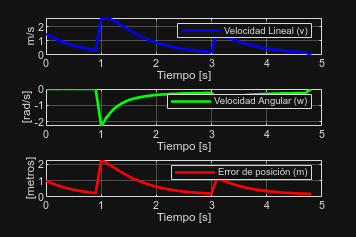


% d) Bucle de simulacion de movimiento del robot
step = 1;
for k = 1:step:N
    delete(H1);
    delete(H2);

    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);

    pause(ts);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);
subplot(311)
plot(t, v, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('Velocidad Lineal (v)');
subplot(312)
plot(t, w, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('Velocidad Angular (w)');
subplot(313)
plot(t, Error, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('[metros]'), legend('Error de posición (m)');